# 6. Processing 2D NMR NOESY

### Introduction

Nuclear Overhauser Effect Spectroscopy ([NOESY](https://www.sciencedirect.com/topics/materials-science/nuclear-overhauser-effect-spectroscopy)). NOESY plays a crucial role in elucidating the spatial arrangement of atoms within a molecule, particularly in the study of biomolecules like proteins and nucleic acids.

Unlike COSY, which investigates through-bond J-couplings, NOESY focuses on through-space interactions between non-bonded nuclei. The technique is predominantly used to observe hydrogen atoms 1H but can also be applied to other nuclei. NOESY is based on the Nuclear Overhauser Effect (NOE), where the relaxation of one nuclear spin influences the relaxation of another nearby nuclear spin. 

In a NOESY experiment, the resulting two-dimensional spectrum provides valuable information on the proximity of atoms. One axis of the NOESY spectrum represents the chemical shift of one nucleus, while the other axis corresponds to the chemical shift of a spatially close nucleus. The presence of cross-peaks in the NOESY spectrum is indicative of the NOE between nuclei. The intensity of these cross peaks is directly related to the distance between the interacting nuclei. Stronger cross peaks usually indicate closer proximity, while weaker peaks suggest a greater distance.

By analyzing the pattern and intensity of cross peaks in a NOESY spectrum, one can infer which atoms are in close proximity within a molecule. This information is crucial for determining the three-dimensional structure of the molecule. NOESY is often used in conjunction with other NMR techniques, like COSY and HSQC, to provide a comprehensive understanding of both the connectivity (through-bond interactions) and the spatial arrangement (through-space interactions) of atoms within a molecule.

### Experimental data import

In this example, we will look at the NOESY of [Ubiquitin](https://www.sciencedirect.com/topics/neuroscience/ubiquitin). It is a small protein consisting of 76 amino acids found in almost all tissues of eukaryotic organisms. It plays a crucial role in various cellular processes. Our dataset has already been exported by the NMR instrument into a [.mat file ](https://www.mathworks.com/help/matlab/ref/matlab.io.matfile.html)that may be loaded and plotted directly. This NMR data is kindly provided by Prof. Ilya Kuprov, University of Southampton.

load('NOESY.mat','fid','XAxis','YAxis');
timeSpectrum=fid;

It is easiest to visualize 2D spectra with contour plots. NOESY spectra are phase sensitive and we want to plot the **Real** part of the spectrum. We create non-linear levels to our contour plot which are sensitive relative to the highest values part of the real spectrum.

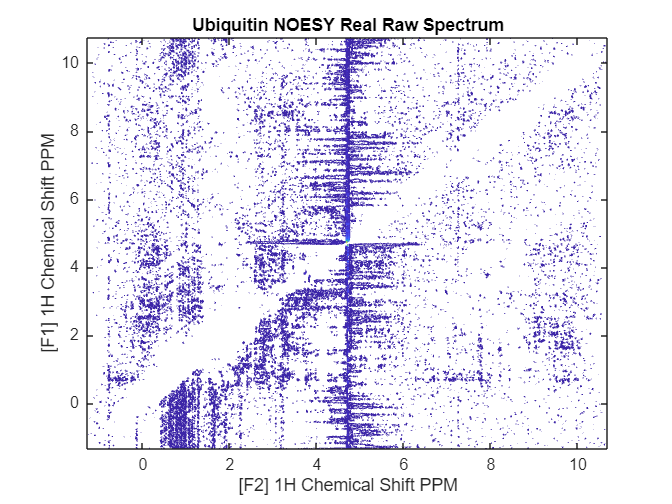

smax=max(real(fft2((timeSpectrum))),[],'all');
levels=0.95*smax*linspace(0,1,20).^2+0.0005*smax;
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right');
contour(XAxis,YAxis,real((fft2((timeSpectrum)))),levels);
title('Ubiquitin NOESY Real Raw Spectrum')
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 1H Chemical Shift PPM')
hold on;

### **Phase correction**

If we investigate the spectrum, we see that the peaks are all over the place. This is because the spectrum is not phase corrected. Phase correction similarly to [apodization](https://web.stanford.edu/group/chem-NMR/help_docs/2dapodization.htm) (see the [COSY example](https://github.com/mathworks/Chemistry-NMR-2D-COSY/tree/main)), is applied to each dimension separately. We can set the 0th and 1st order phase correction in the same manner as in 1D spectra, except now it is applied to each row and column (F1 and F2 dimensions). In this example we can do this with a very simple function which requires the 0th,1st order corrections, the spectrum, and the dimension of application.    

% Convert full spectrum FID to frequency domain
signal=fft2(timeSpectrum);

% Apply Phase correction with the specified 0th and 1st order to the F2
% dimension (degrees)
signal = PhaseCorrection(100, 0, signal, 'rows');

% Apply Phase correction with the specified 0th and 1st order to the F1
% dimension (degrees)
signal = PhaseCorrection(-80, 0, signal, 'columns');

Let us look at the phase corrected NOESY spectrum. It has exponentially improved, we can now clearly see the diagonal peaks arising from the 1H spectra on both axis. However, more importantly we can now see the cross peaks on each side of the diagonal. Chemists can use the intensities and positions of the cross peaks to analyze the spatial distance of the nuclei.

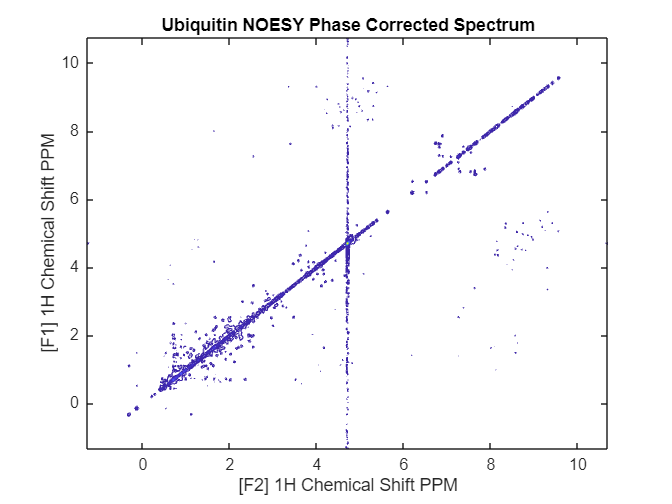

figure()
smax_real=max(real(signal),[],'all');
real_levels=0.95*smax_real*linspace(0,1,20).^2+0.0005*smax_real;
set(gca,'XDir','reverse','YDir','reverse','YAxisLocation','right');
contour(XAxis,YAxis,real(signal),real_levels);
xlabel('[F2] 1H Chemical Shift PPM')
ylabel('[F1] 1H Chemical Shift PPM')
title('Ubiquitin NOESY Phase Corrected Spectrum')
hold on;

### Summary

We have introduced the NOESY experiment and explained how the cross-peak signals holds spatial information of organic molecules. However, to interpret the NOESY spectra the time domain data needs to be processed so we can identify the individual peaks. This is done by enhancing signals through apodization and phase correction. We applied phase corrected both dimensions of the spectrum, so the cross peaks are more easily visible.

### **Utility Function**

function phaseCorrectedSignal=PhaseCorrection(phc0,phc1,signal,dimension)
    switch dimension
        case 'rows'
            numPoints=numel(signal(:,1));
            % Convert phase correction to radians
            phc0=deg2rad(phc0);

            % This multiplicity factor for 1st order correction
            phc1=deg2rad(phc1)/numPoints;         

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F1
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=signal.*phaseCorrection;
        case 'columns'
            numPoints=numel(signal(1,:));
            % Convert phase correction to radians
            phc0=deg2rad(phc0);
            phc1=deg2rad(phc1)/numPoints;   

            freq=linspace(1,numPoints,numPoints);

            % Apply the 0th and 1st order phase correction in F2
            phaseCorrection=exp(+1i*(phc0 + (phc1*freq')));
            phaseCorrectedSignal=signal.*phaseCorrection';
    end
end
